# List With Buttons

## Create the widget

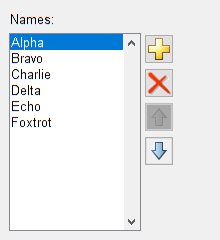

% This widget behaves like a List widget, but adds buttons for sorting and
% other functionality. 

f = figure(...
    'Toolbar','none',...
    'MenuBar','none',...
    'NumberTitle','off',...
    'Units','pixels',...
    'Position',[100 100 220 240]);
movegui(f,[100 -100])

w = uiw.widget.ListWithButtons(...
    'Parent', f, ...
    'Items',{'Alpha','Bravo','Charlie','Delta','Echo','Foxtrot'},...
    'AllowAdd', true, ... %Requires callback implementation
    'AllowCopy', false, ... %Requires callback implementation
    'AllowDelete', true, ... %Requires callback implementation
    'AllowEdit', false, ... %Requires callback implementation
    'AllowMove', true, ... %Callback is optional
    'AllowPlot', false, ... %Requires callback implementation
    'AllowReverse', false, ... %Requires callback implementation
    'AllowRun', false, ... %Requires callback implementation
    'Callback',@(h,e)disp(e.Interaction),...
    'ButtonLocation','right',...
    'Label','Names:', ...
    'LabelLocation','top',...
    'LabelHeight',18,...
    'Units', 'pixels', ...
    'Position', [10 10 200 220]);

## Set by index

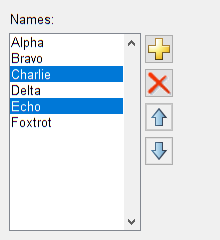

w.AllowMultiSelect = true;
w.SelectedIndex = [3 5];

## Get the selected items

% This is a read-only property
selection = w.SelectedItems

selection = 1×2 cell array
    {'Charlie'}    {'Echo'}
